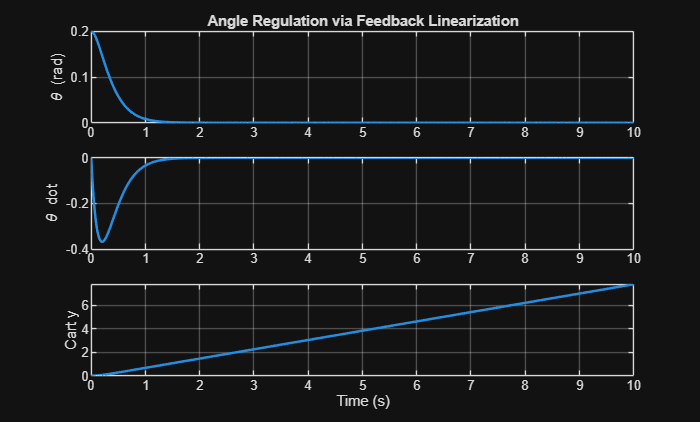

clc; clear; close all;

%% Physical parameters
m = 0.2;      % pendulum mass
M = 1.0;      % cart mass
L = 0.5;      % distance CoG to pivot
J = 0.006;    % pendulum inertia about CoG
k = 0.05;     % viscous friction coefficient
g = 9.81;

params = [m M L J k g];

%% Feedback-linearization gains (for theta regulation)
k1 = 25;    % stiffness
k2 = 10;    % damping
K = [k1 k2];

%% Initial condition [theta, theta_dot, y, y_dot]
x0 = [0.2; 0; 0; 0];    % small angle deviation

%% Simulate
tspan = [0 10];
[t, x] = ode45(@(t,x) pendulum_FL(t, x, params, K), tspan, x0);

%% Extract variables
theta     = x(:,1);
theta_dot = x(:,2);
y         = x(:,3);
y_dot     = x(:,4);

%% Plot results
figure; 
subplot(3,1,1); plot(t,theta,'LineWidth',1.5); grid on;
ylabel('\theta (rad)'); title('Angle Regulation via Feedback Linearization');

subplot(3,1,2); plot(t,theta_dot,'LineWidth',1.5); grid on;
ylabel('\theta dot');

subplot(3,1,3); plot(t,y,'LineWidth',1.5); grid on;
ylabel('Cart y'); xlabel('Time (s)');

function dx = pendulum_FL(t, x, params, K)
    % State variables
    theta = x(1);
    dtheta = x(2);
    y = x(3);
    dy = x(4);

    % Parameters
    m = params(1); 
    M = params(2);
    L = params(3);
    J = params(4);
    k = params(5);
    g = params(6);

    % Short-hand notation
    a1 = J + m*L^2;
    a2 = M + m;
    b  = m*L;
    c  = cos(theta);
    s  = sin(theta);

    Delta = a1*a2 - (b^2)*(c^2);

    %% Compute f1(x)
    term1 = a2*b*g*s;
    term2 = -b^2 * c * dtheta^2 * s;
    term3 = b*c*k*dy;

    f1 = (term1 + term2 + term3) / Delta;

    %% Compute g1(x)
    g1 = -(b * c) / Delta;

    %% New input (desired linearized dynamics)
    v = -K(1)*theta - K(2)*dtheta;   % makes ddtheta = v

    %% Compute force input F
    F = (v - f1) / g1;

    %% Now compute ddtheta and ddy for the true nonlinear system
    % Right-hand side for full dynamics
    RHS1 = b*g*s;
    RHS2 = F + b*(dtheta^2)*s - k*dy;

    dd = (1/Delta) * [ a2  -b*c; 
                      -b*c  a1 ] * [RHS1; RHS2];

    ddtheta = dd(1);
    ddy = dd(2);

    %% Return dx
    dx = zeros(4,1);
    dx(1) = dtheta;
    dx(2) = ddtheta;
    dx(3) = dy;
    dx(4) = ddy;
end
